# TASK 1 and 2

Name: Zhu Chenhao

HDU ID: 22320630

ITMO ID: 375462

sys1 = tf(5, [2, 6]);
A1 = -3; 
B1 = 5/2; 
C1 = 1;
H1 = ss(A1, B1, C1, []);
W1 = tf(H1);

sys2 = tf(2, [7, 4, 1]);
A2 = [0, 1; -1/7, -4/7];
B2 = [0; 2/7];
C2 = [1 0];
H2 = ss(A2, B2, C2, []);
W2 = tf(H2);

sys3 = tf(1, [1, 0, 3]);
A3 = [0, 1; -3, 0];
B3 = [0; 1];
C3 = [1 0];
H3 = ss(A3, B3, C3, []);
W3 = tf(H3);

sys4 = tf([1, 0], [13, 4]);
A4 = -4/13;
B4 = 1;
C4 = 1;
D4 = 0;
H4 = ss(A4, B4, C4, D4);
W4 = tf(H4);

sys5 = tf([1, 2], [2.5, 12, 5]);
A5 = [0, 1; -5/2.5, -12/2.5];
B5 = [0; 1];
C5 = [2-1*(-12/2.5)/2.5, 1/2.5];
D5 = 0;
H5 = ss(A5, B5, C5, D5);
W5 = tf(H5);

sys6 = tf(1, [1, 6, 634]);
A6 = [0, 1; -634, -6];
B6 = [0; 1];
C6 = [1 0];
H6 = ss(A6, B6, C6, []);
W6 = tf(H6);

sys7 = tf(1, [1, -0.2, 4.01]);
A7 = [0, 1; -4.01, 0.2];
B7 = [0; 1];
C7 = [1 0];
H7 = ss(A7, B7, C7, []);
W7 = tf(H7);

## 1

eig(sys2)

ans =   -0.2857 + 0.2474i
  -0.2857 - 0.2474i


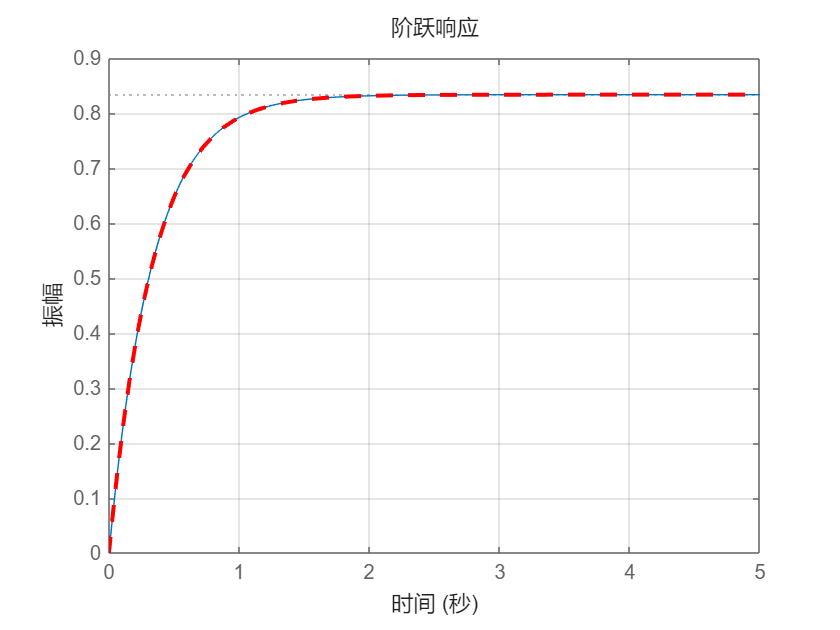

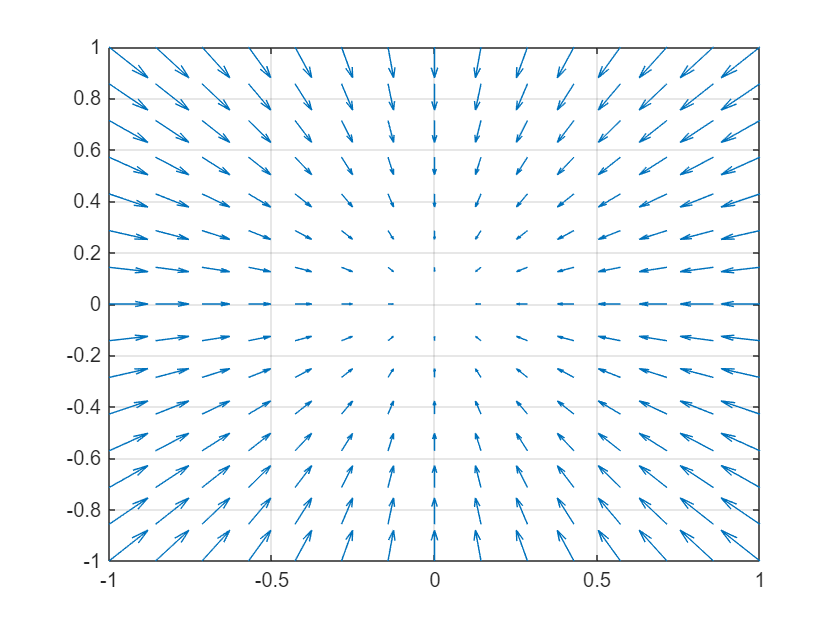

plot_phase(H1, A1, B1, C1, 5, 15);

## 2

eig(sys2)

ans =   -0.2857 + 0.2474i
  -0.2857 - 0.2474i


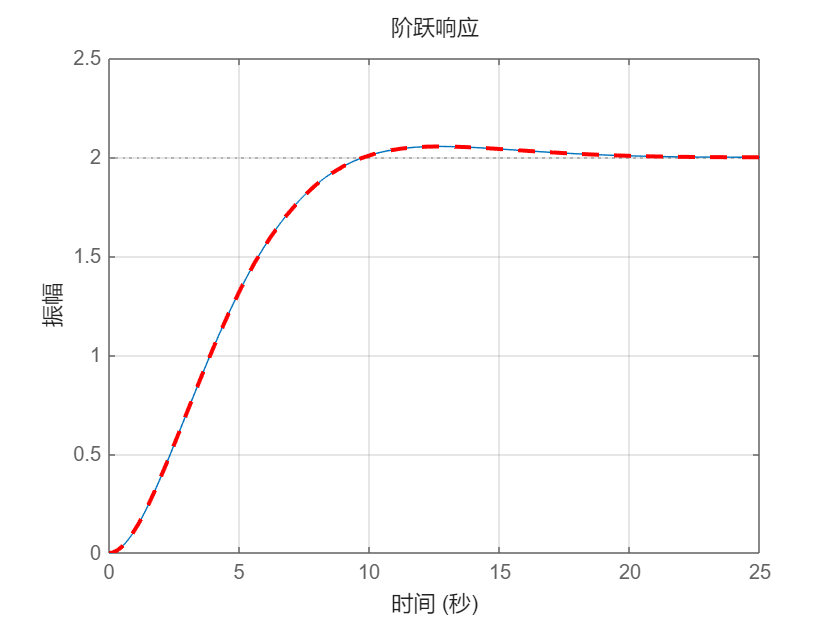

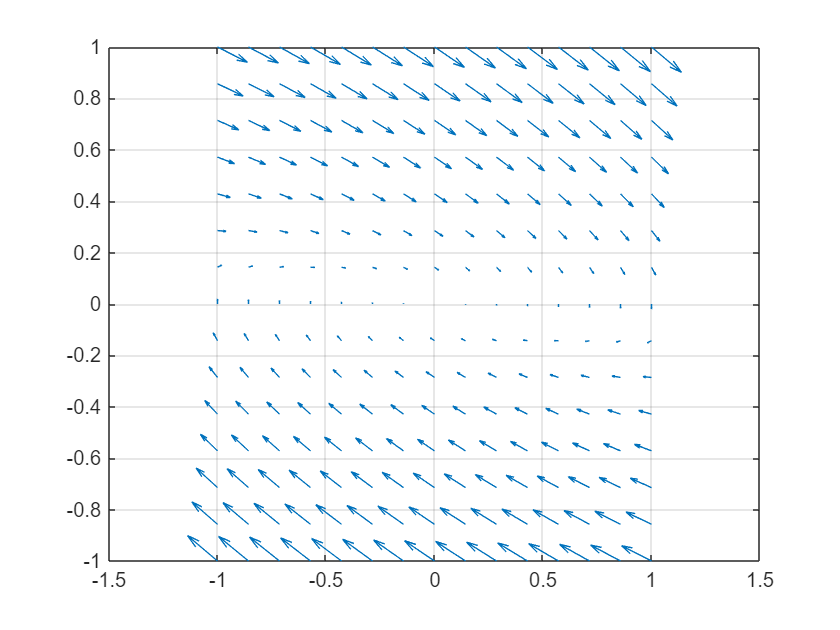

plot_phase(H2, A2, B2, C2, 25, 15);

## 3

eig(sys3)

ans =    0.0000 + 1.7321i
   0.0000 - 1.7321i


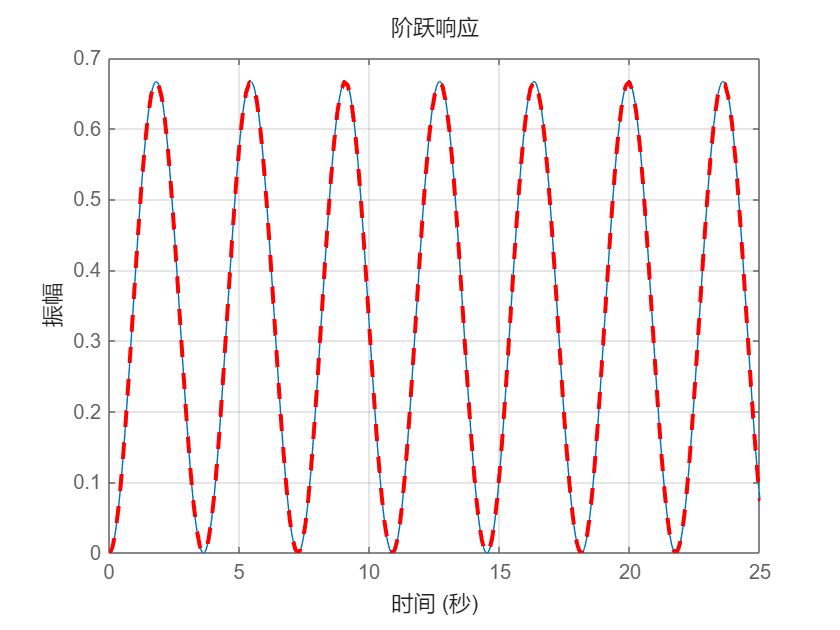

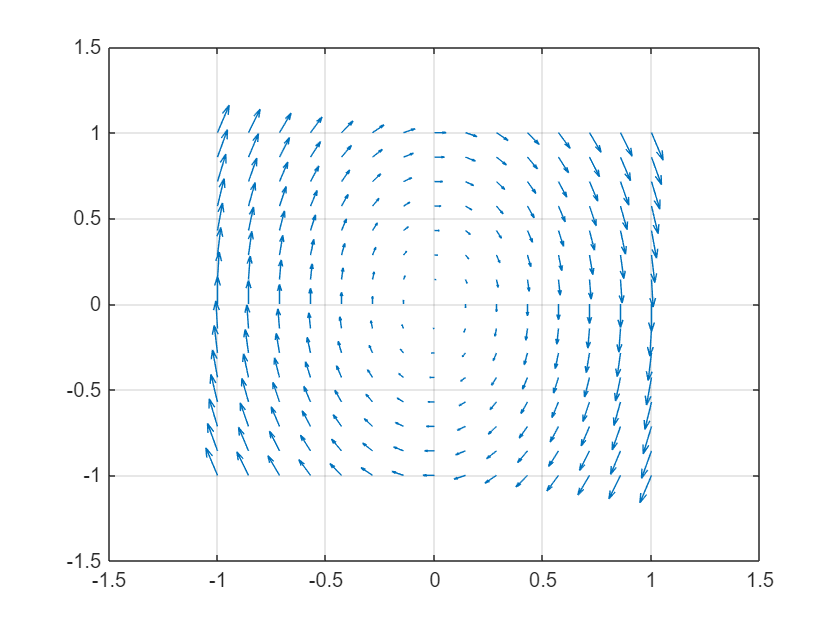

plot_phase(H3, A3, B3, C3, 25, 15);

## 4

eig(sys4)

ans = -0.3077

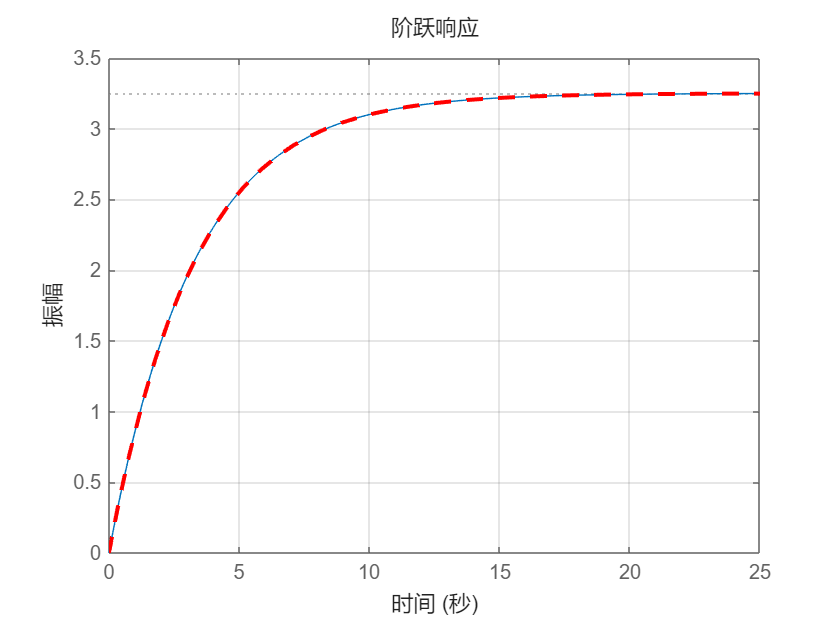

plot_phase(H4, A4, B4, C4, 25, 15);

## 5

eig(sys5)

ans =    -4.3391
   -0.4609


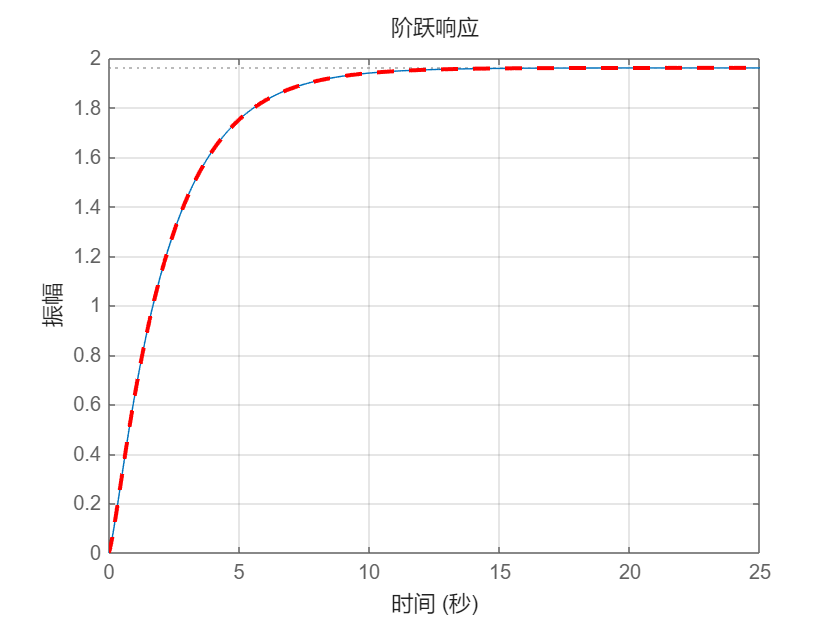

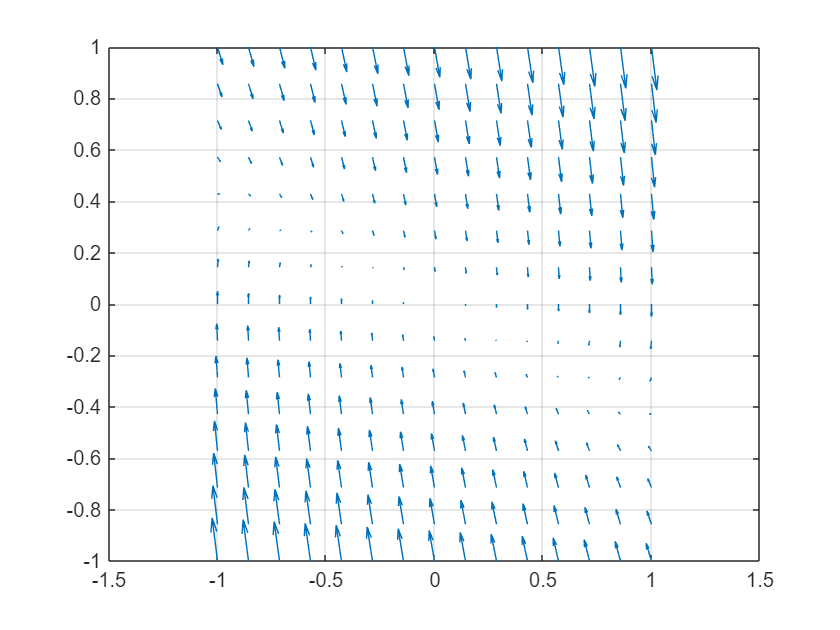

plot_phase(H5, A5, B5, C5, 25, 15);

## 6

eig(sys6)

ans =   -3.0000 +25.0000i
  -3.0000 -25.0000i


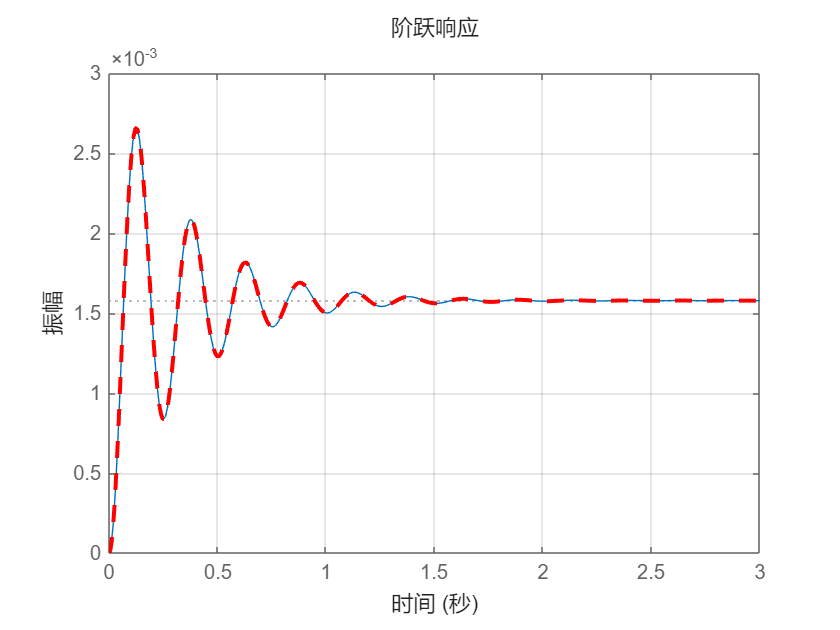

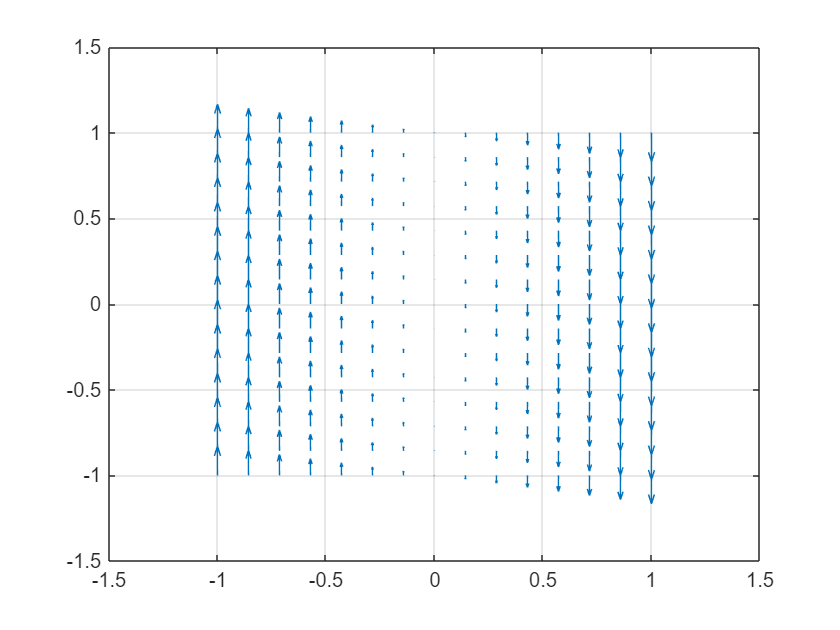

plot_phase(H6, A6, B6, C6, 3, 15);

## 7

eig(sys7)

ans =    0.1000 + 2.0000i
   0.1000 - 2.0000i


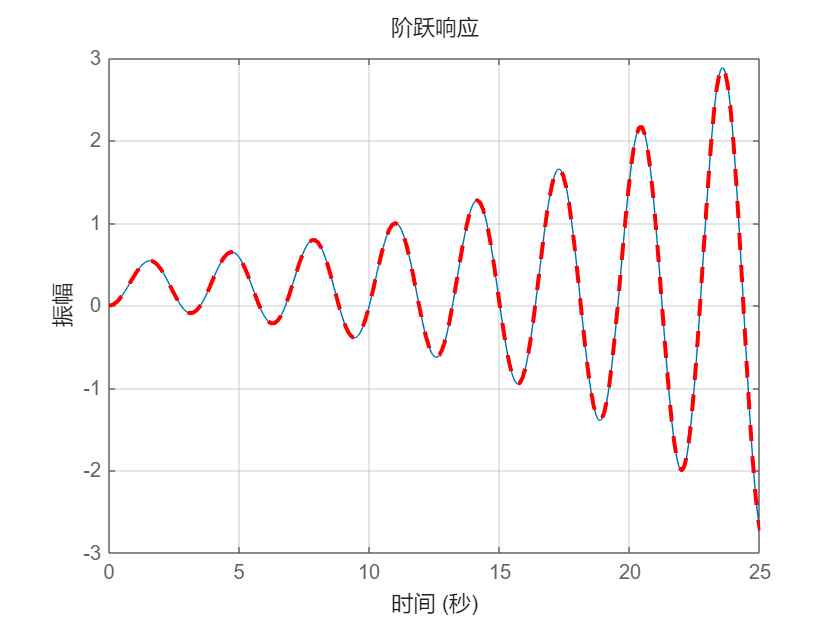

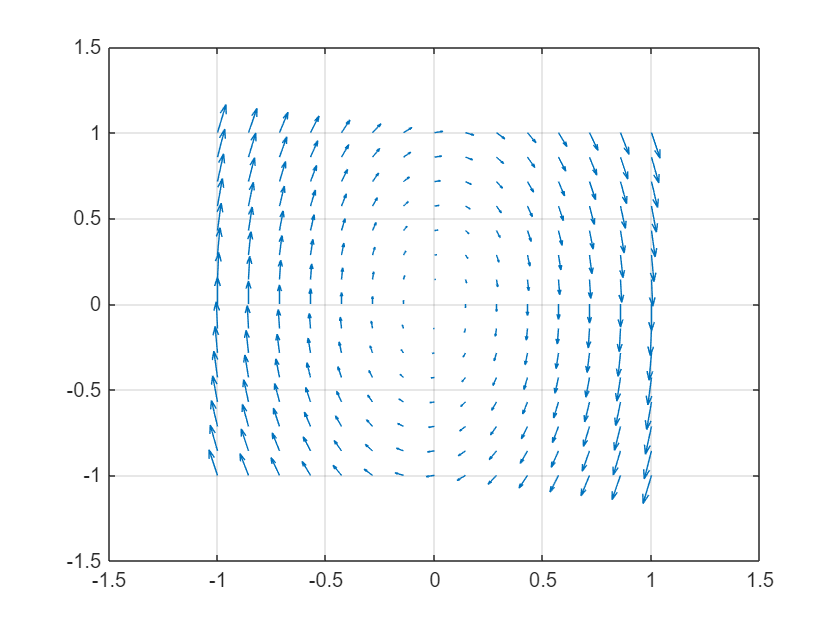

plot_phase(H7, A7, B7, C7, 25, 15);

# Function

function dxdt = odefcn(t, x, A, B, C)
    u = 1;
    dxdt = A*x + B*u;
end

function plot_phase(H, A, B, C, t_end, n)
    t = 0:0.01:t_end;
    figure;
    step(H, t);
    
    hold on;grid on;
    [t, x] = ode45(@(t, x) odefcn(t, x, A, B, C), [0, t_end], [0, 0]);
    
    
    plot(t, x * C', '--r', 'LineWidth', 2);
    x1 = linspace(-1, 1, n);
    x2 = linspace(-1, 1, n);
    [X1, X2] = meshgrid(x1, x2);
    dX1 = zeros(size(X1));
    dX2 = zeros(size(X2));
    for i = 1:n
        for j = 1:n
            x = [X1(i, j); X2(i, j)];
            u = 0;
            dx = A*x+B*u;
            dX1(i,j) = dx(1);
            dX2(i,j) = dx(2);
    
        end
    end
    figure;
    quiver(X1, X2, dX1, dX2);
    grid on;
end